# DobotSim.mlx

This script does the following:

- Sets up Dobot collision body object for simulation

- Sets up paths for tracing on paper (XY plane)

- Tests Forward and Inverse Kinematics in Tracing the S Path

## 1: Setup Dobot Simulation Object

clear; clc; close all;
addpath DobotKinematics\
addpath Paths\

Define base reference axes

zz = zeros(3,1); ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];

Define Dobot arm geometry

% arm lengths (m)
% l1 = .103;
% l2 = .135;
% l3 = .160;
% l4 = .050;
% l5 = .075;

% arm lengths (mm)
l1 = 101;
l2 = 135;
l3 = 160;
l4 = 50;
l5 = 95;

p01 = l1*ez;
p12 = zz;
p23 = l2*ez;
p34 = l3*ex;
p4T = l4*ex - l5*ez;

h1 = ez;
h2 = ey; h3 = ey; h4 = ey;

Define Dobot parameters and collisionBody

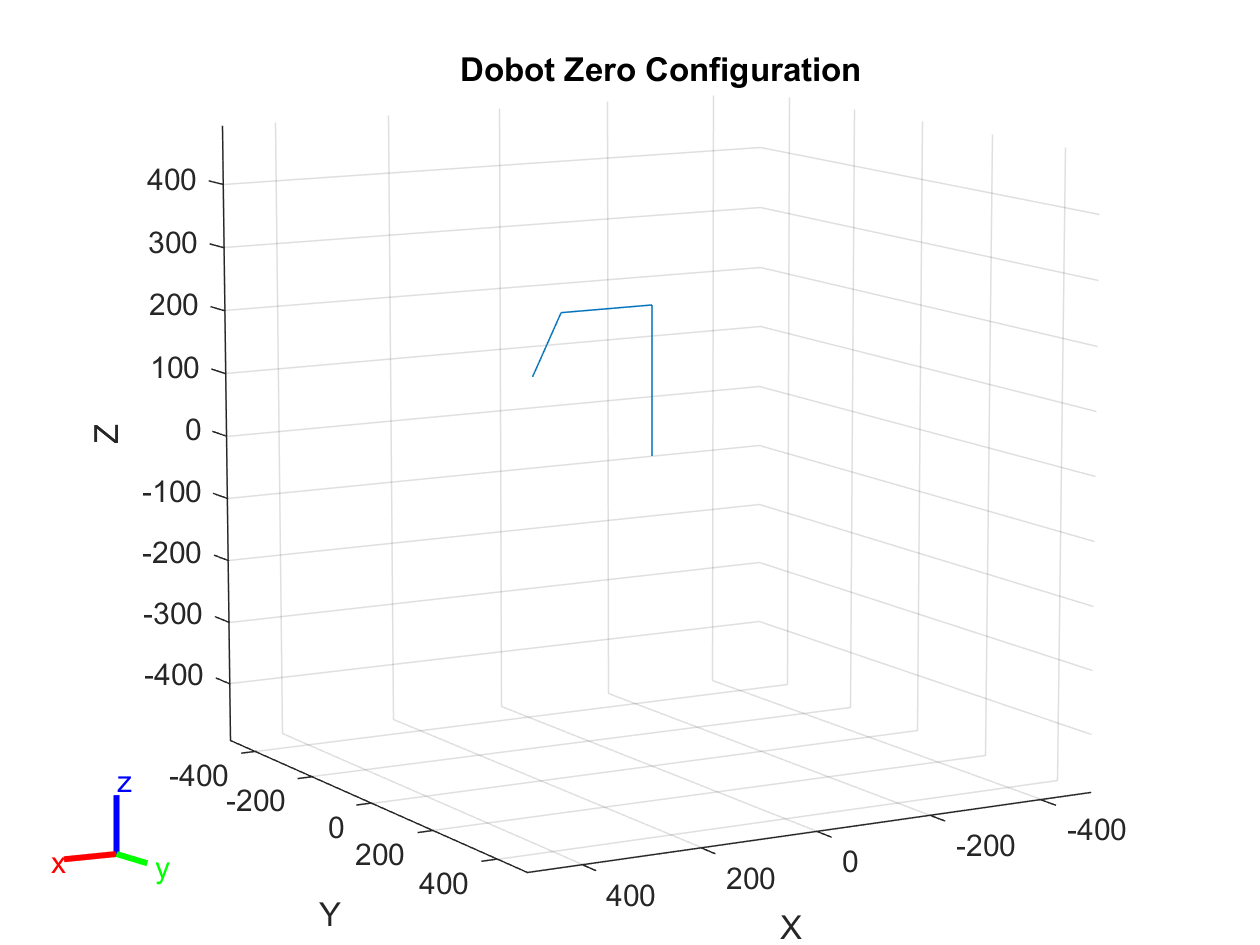

dobot.P = [p01 p12 p23 p34 p4T];
dobot.H = [h1 h2 h3 h4];
dobot.joint_type = zeros(1,4);

radius=.01;
[dobot_rbt, colLink] = defineRobot(dobot, radius);

q0 = zeros(4,1); % joint angles in zero config
figure(1); show(dobot_rbt, q0, 'collision', 'on');
view(150,10)
title("Dobot Zero Configuration")

Setup S-path on X-Y Plane with corresponding end effector frame

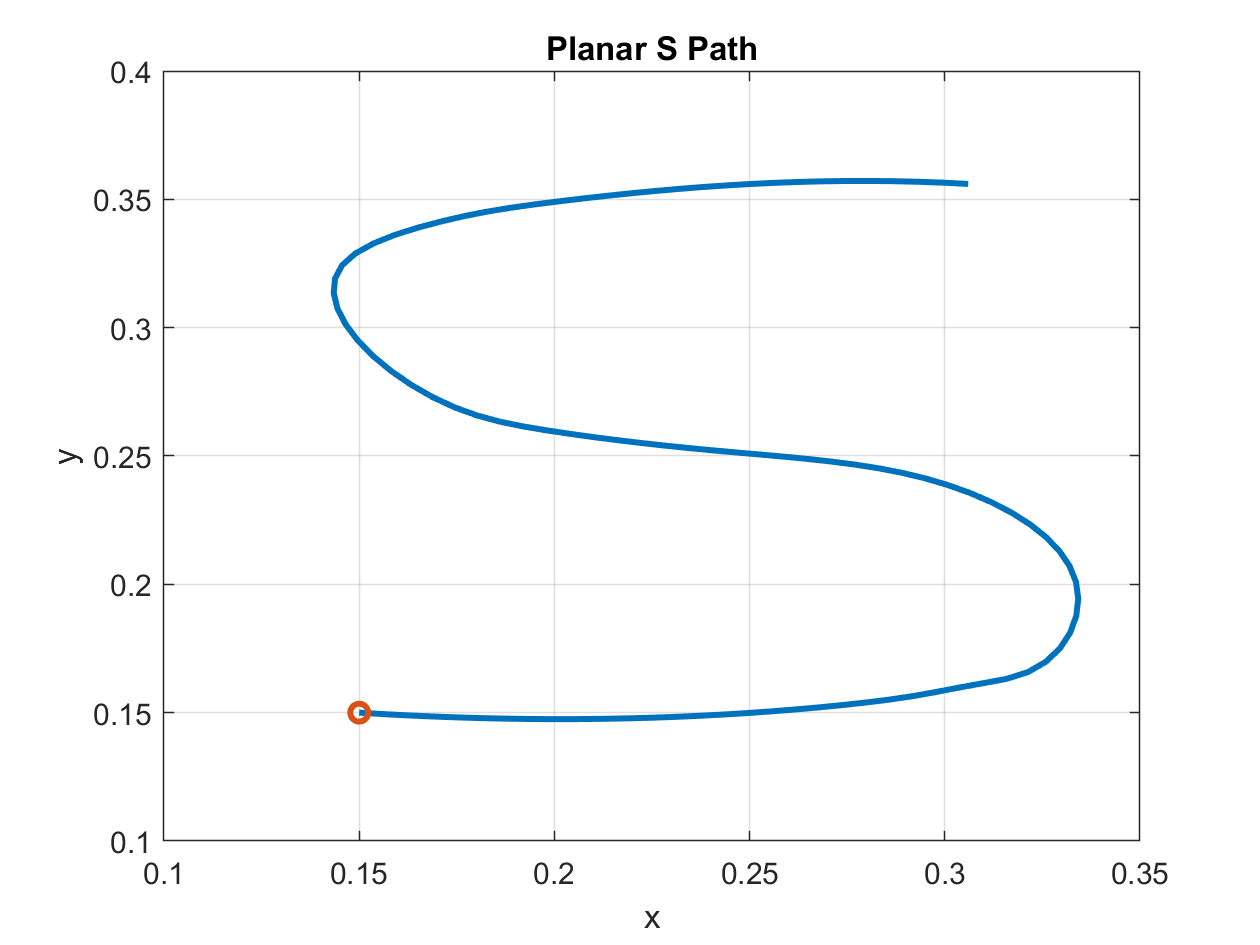

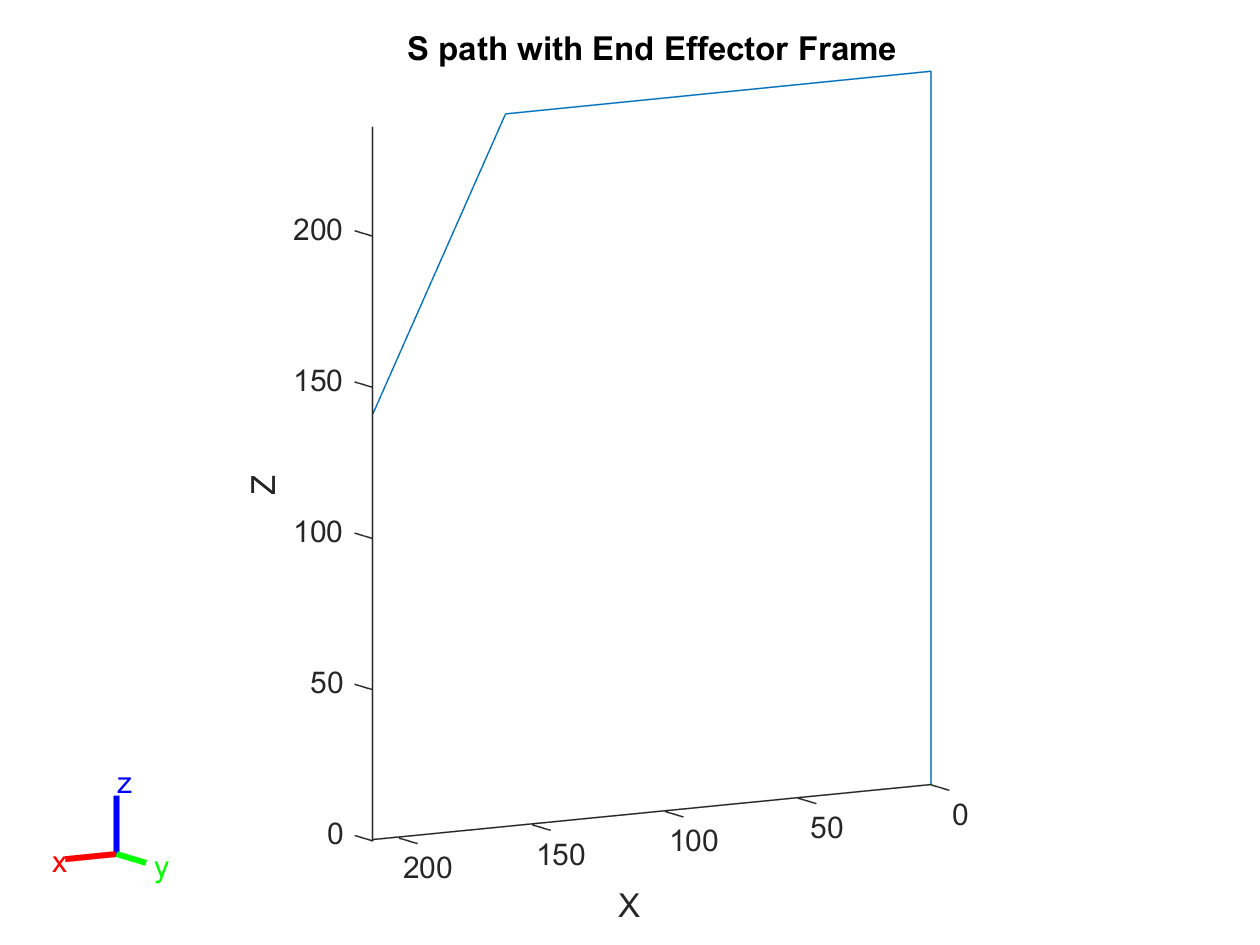

defineSPath;

## 2: Dobot Forward and Inverse Kinematics

Use Inverse Kinematics to Trace S on the XY Plane

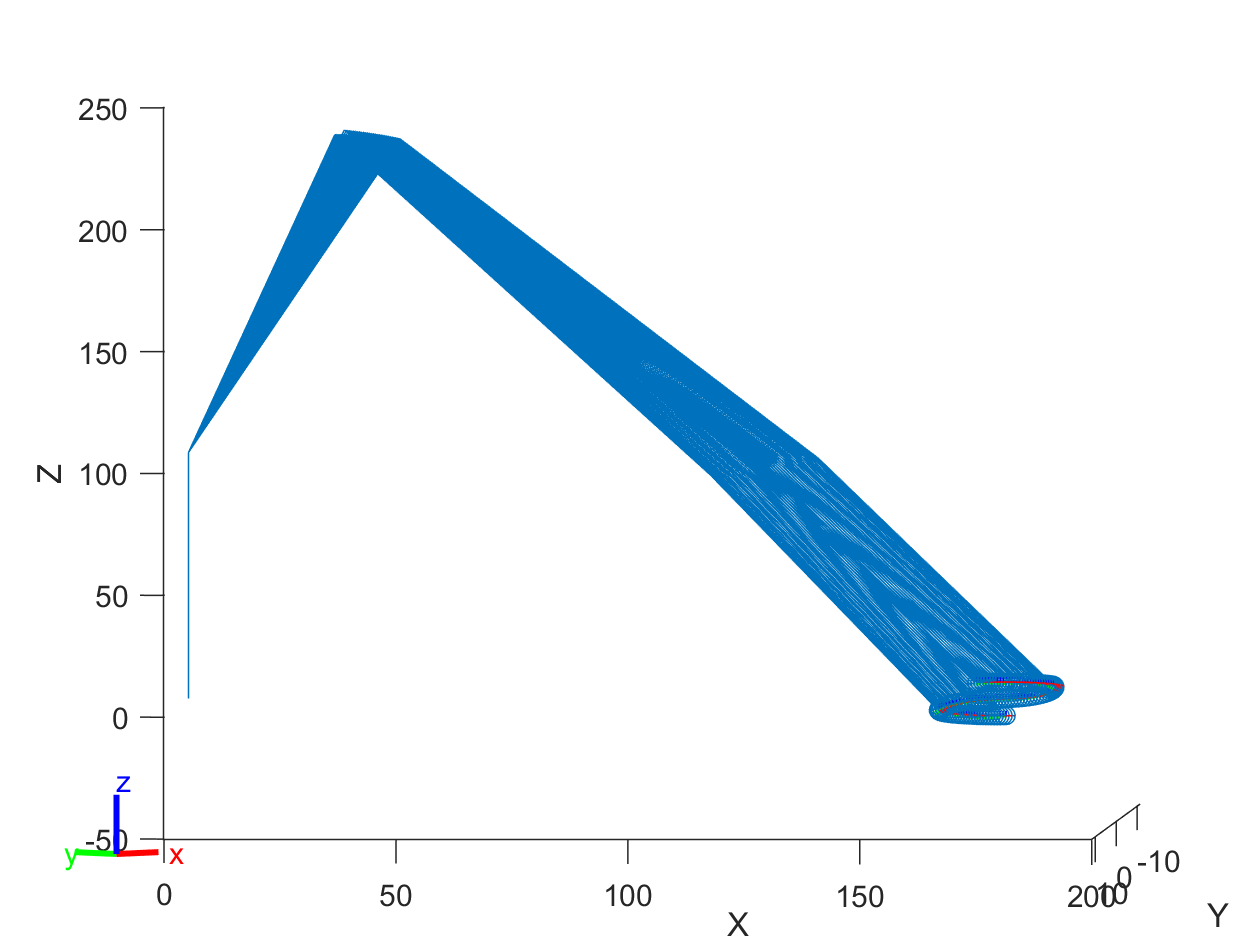

pp = 1000*pS;
% shift S to be in front of Dobot
pp = pp./10;
pp(1:2,:) = pp(1:2,:) + [150; -26];



% find end effector frame for all points in the path
N = length(pp);
for i=1:N   
    xT(:,i)=(pp(:,i))/norm(pp(:,i)); % unit vector from base to point in path
    yT(:,i) = rot(ez,pi/2)*xT(:,i); % yT = Rotation of xT about z by 90 degrees
    zT(:,i)=cross(xT(:,i),yT(:,i)); % zT = xT x yT always into the paper
    R = [xT(:,i) yT(:,i) zT(:,i)];
    quat(:,i) = rotm2quat(R);
end

% dobot = fwddiffkiniter(dobot);

figure(5);
plot3(pp(1,:), pp(2,:), pp(3,:), '-o'); hold on
h = plotTransforms(pp', quat', 'FrameSize', 2);
for i = 1:length(pp)
    dobot.T = [[xT(:,i) yT(:,i) zT(:,i)] pp(:,i); [0 0 0 1]];
    dobot = invkin(dobot);
    dobot = anglelim(dobot);
%     dobot.q(4) = -(dobot.q(3) + dobot.q(2));
%     if pp(2,i) > 0
%         dobot.q(4) = -(dobot.q(4) + pi);
%     end
    show(dobot_rbt, dobot.q, 'collision', 'on'); hold on
end
xlabel("X"); ylabel("Y"); zlabel("Z");